                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

data = table2array(readtable('../../data/data1/CHID46.csv'));
dpi = data(:,1);
y = data(:,2);
num_pat = 1;



h = 0.01;
ti = 0:h:dpi(end); 
init = [10^4 0 10^-3];

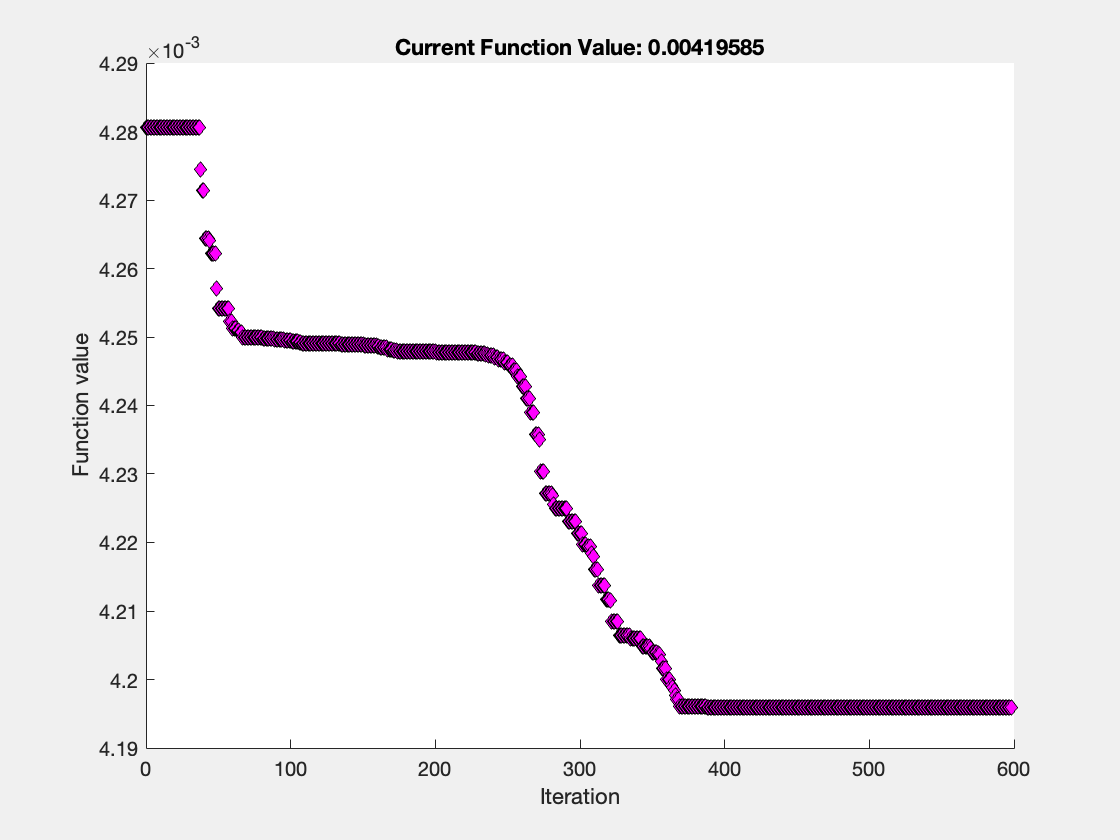

Optimization terminated prematurely by user.


N = 5;
out = zeros(N,8);

x0 = [0.409*10^-6 0.233*10^-6 0.249 0.775 14.5*10^3 0.03 7];
out(1,1) = J(x0, ti, init, h, dpi, y);
out(1,2:end) = x0;

x1 = [2.0209E-7 1.2719E-7 0.41184 1.52453 41085.62299 0.03901 6];
out(2,1) = J(x1, ti, init, h, dpi, y);
out(2,2:end) = x1;


[bp, fval] = best_param(x1,dpi,y);

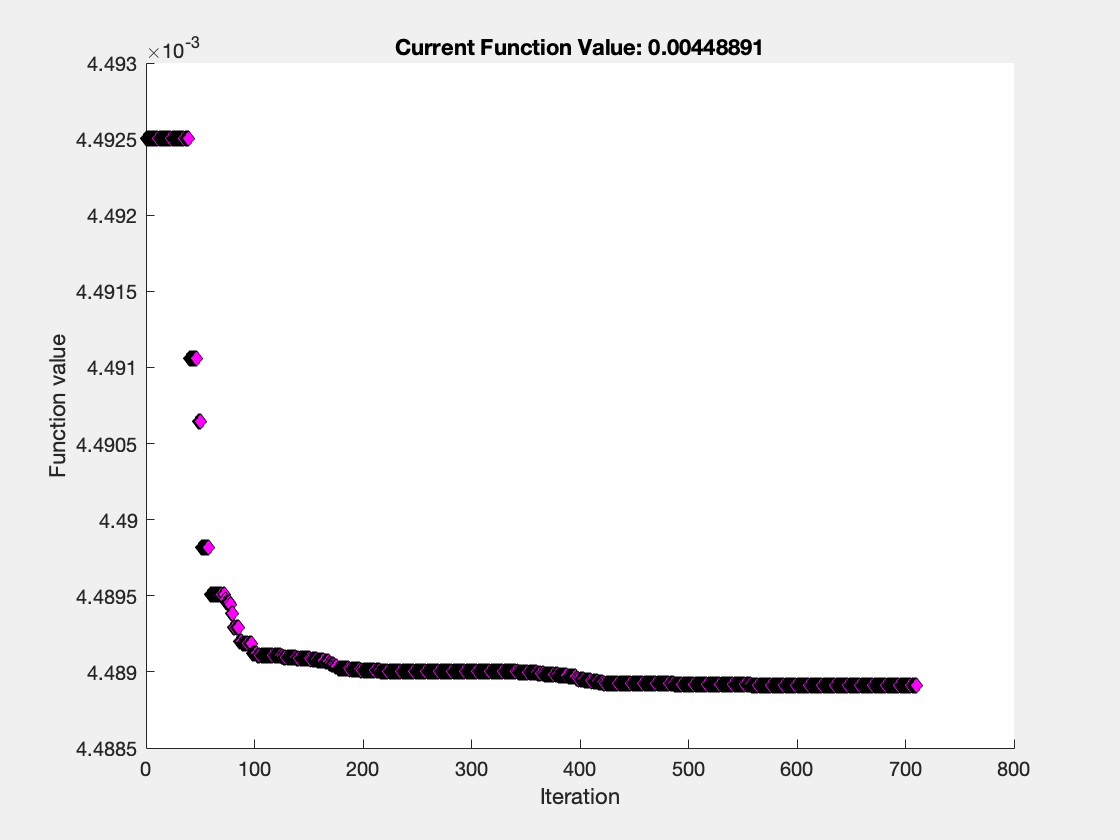

Optimization terminated prematurely by user.


out(3,1) = fval;
out(3,2:end) = bp;

x2 = [2.0273E-7, 1.2499E-7, 1.81286, 1.57038, 42987.62471, 0.03935, 7];
out(4,1) = J(x1, ti, init, h, dpi, y);
out(4,2:end) = x2;


[bp, fval] = best_param(x2,dpi,y);

out(5,1) = fval;
out(5,2:end) = bp;

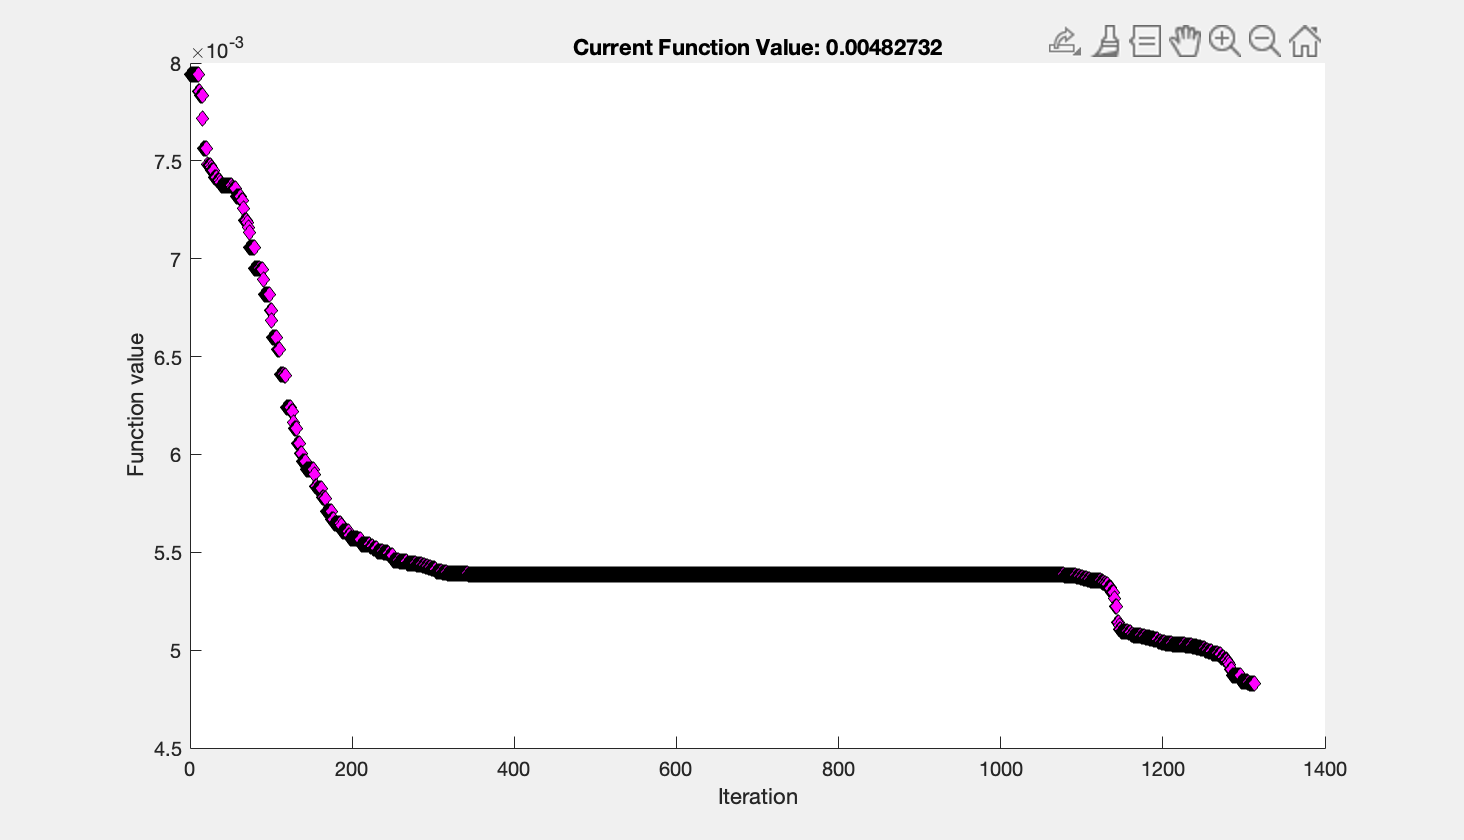

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.004827 



[bp, fval] = best_param(x0,dpi,y);

bp

array2table(bp)

ans = 1×7 table
       bp1           bp2         bp3       bp4      bp5       bp6        bp7 
    __________    __________    ______    _____    _____    ________    _____

    3.8026e-07    1.7524e-07    1.1178    1.091    24591    0.034322    3.871


p1 = pred(ti,init,x0(1),x0(2),x0(3),x0(4),x0(5),x0(6),x0(7))

p1 = 1.0e+05 *

    0.1000         0    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000
    0.1000    0.0000    0.0000


plot(ti,log10(p1(:,3)))
hold on 
p2 = pred(ti,init,x1(1),x1(2),x1(3),x1(4),x1(5),x1(6),x1(7))

p2 = 1.0e+06 *

    0.0100         0    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000
    0.0100    0.0000    0.0000


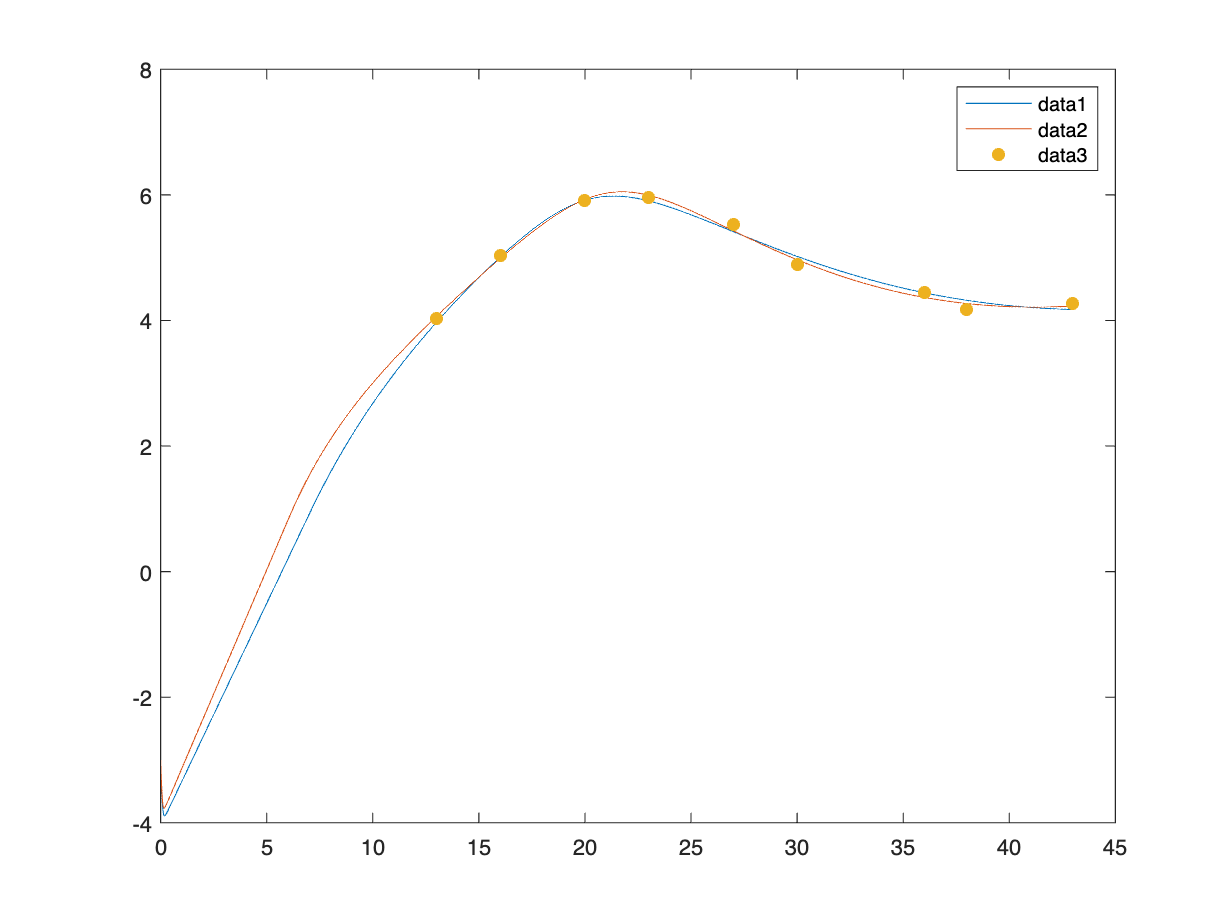


plot(ti,log10(p2(:,3)))
hold on 
legend

scatter(dpi,y,'filled')

hold off

disp(out(1,1) )

    0.0079



disp(out(2,1) )

    0.0043



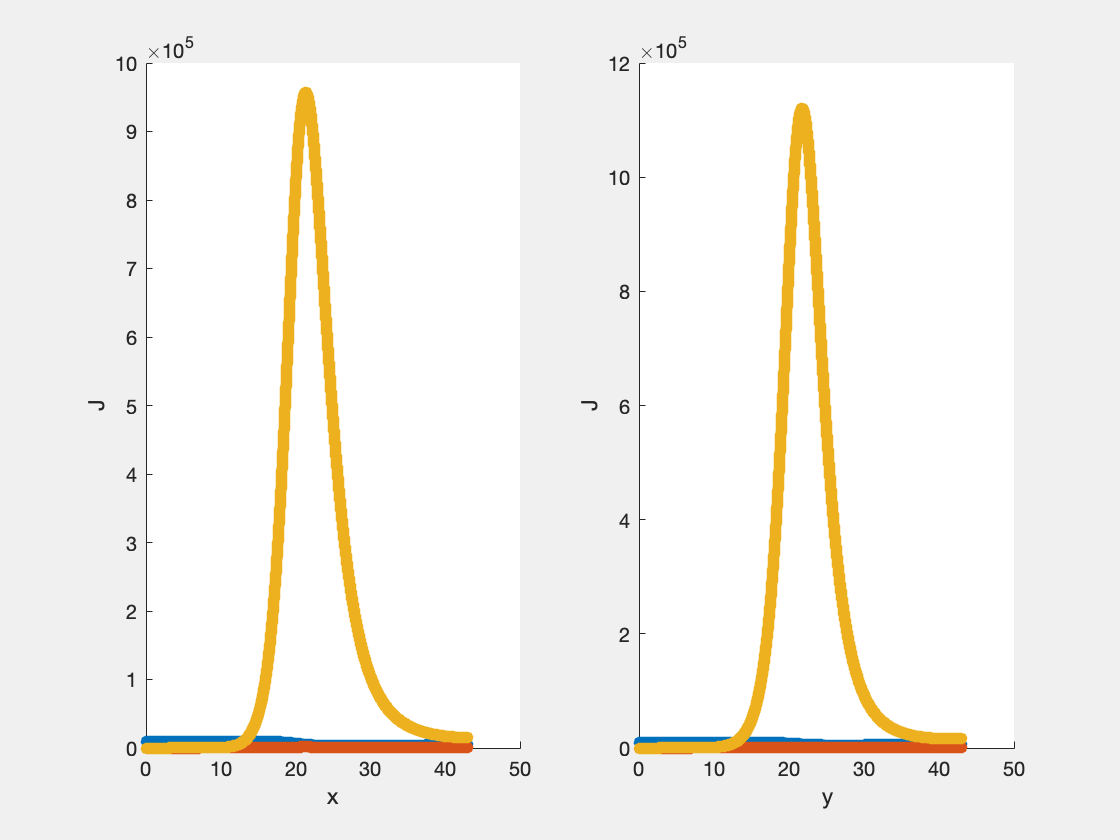

% subplot(1,2,1)
% scatter(ti,pred(ti,init,x0(1),x0(2),x0(3),x0(4),x0(5),x0(6),x0(7)),'filled')
% xlabel('x');
% ylabel('J');
% 
% subplot(1,2,2)
% scatter(ti,pred(ti,init,x1(1),x1(2),x1(3),x1(4),x1(5),x1(6),x1(7)),'filled')
% xlabel('y');
% ylabel('J'); 

tb = array2table(out,...
            'VariableNames', ...
            {'J','b0','bi','k','dlt','p','d','tau'});
writetable(tb, 'results.csv');

%% decay function 

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end


function out = pred(ti,init,b0,bi,k,dlt,p,d,tau)

    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa;
 
end

function out=J(params, ti,init,h, dpi,y)
    
    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);

    xa = pred(ti,init,b0,bi,k,dlt,p,d,tau);
    V = xa(:,3);

    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

function [x,fval]=best_param(x0,dpi,y,ti,init,h) %,lb,ub)
    h = 0.01;
    ti = 0:h:dpi(end); 
    init = [10^4 0 10^-3];

    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 2000);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
    [x,fval] = fminsearch(JJ,x0,options);
end 

% function [x,fval]=best_param2(x0,dpi,y,lb,ub)
%     h = 0.01;
%     ti = 0:h:dpi(end); 
%     init = [10^4 0 10^-3];
% 
%     options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
%     JJ = @(params) J(params, ti,init,h, dpi,y); 
%     [x,fval] = fmincon(JJ,x0,[],[],[],[],lb,ub,[],options);
% end 

